# Taller 3. Análisis Numérico y Computación Científica

Valentina Pabón

## 1. Métodos directos para resolver sistemas lineales:

### a. 

Resuelva los siguientes sistemas de ecuaciones empleando los métodos de eliminación gaussiana con sustitución hacia atrás, pivoteo parcial y pivoteo escalado. Concluya a partir de la comparación con la solución exacta y con el número de operaciones entre los tres métodos:

#### i. $2x_1 - 6x_2 - x_3  = -38 \\
-3x_1 - x_2 + 7x_3 = -34 \\
-8x_1 + x_2 - 2x_3 = -20 \\
$

A = [2, -6, -1; -3, -1, 7; -8, 1, -2];
b = [-38; -34; -20];

x_exact = linsolve(A, b);
for i = 1:length(x_exact)
    fprintf('La solucion exacta de x%d es = %f\n', i, x_exact(i));
end

La solucion exacta de x1 es = 4.000000
La solucion exacta de x2 es = 8.000000
La solucion exacta de x3 es = -2.000000



% Eliminacion Gaussiana
x = ElimiGausiana(A, b);

Número total de iteraciones en Eliminación Gaussiana: 9


for i = 1:length(x)
    fprintf('La solucion de x%d con eliminacion Gaussiana es = %f\n', i, x(i));
end

La solucion de x1 con eliminacion Gaussiana es = 4.000000
La solucion de x2 con eliminacion Gaussiana es = 8.000000
La solucion de x3 con eliminacion Gaussiana es = -2.000000



% Pivoteo parcial
[x_pivot, A_pivot, b_pivot] = pivoteo_parcial(A, b);

Número total de iteraciones en Pivoteo Parcial: 8


fprintf('Matriz A = \n'); disp(A_pivot);

Matriz A = 
   -8.0000    1.0000   -2.0000
         0   -5.7500   -1.5000
         0         0    8.1087



fprintf('Vector b = \n'); disp(b_pivot);

Vector b = 
  -20.0000
  -43.0000
  -16.2174



for i = 1:length(x_pivot)
    fprintf('La solucion de x%d con pivoteo parcial es = %f\n', i, x_pivot(i));
end

La solucion de x1 con pivoteo parcial es = 4.000000
La solucion de x2 con pivoteo parcial es = 8.000000
La solucion de x3 con pivoteo parcial es = -2.000000



% Pivoteo Escalado
[x_scale, A_scale, b_scale] = pivoteo_escalado(A, b);

Número total de iteraciones en Pivoteo Escalado: 16


fprintf('Matriz A = \n'); disp(A_scale);

Matriz A = 
   -8.0000    1.0000   -2.0000
         0   -5.7500   -1.5000
         0         0    8.1087



fprintf('Vector b = \n'); disp(b_scale);

Vector b = 
  -20.0000
  -43.0000
  -16.2174



for i = 1:length(x_scale)
    fprintf('La solucion de x%d con pivoteo escalado es = %f\n', i, x_scale(i));
end

La solucion de x1 con pivoteo escalado es = 4.000000
La solucion de x2 con pivoteo escalado es = 8.000000
La solucion de x3 con pivoteo escalado es = -2.000000


Se puede observar que cada método nos da las mismas soluciones que al calcular la solución exacta. En cuanto al número de iteraciones de cada método, el de pivoteo parcial fue el de menor cantidad.

#### ii. $-3x_2 + 7x_3 = 2 \\
x_1 + 2x_2 - x_3 = 3 \\
5x_1 - 2x_2 = 2
$

A2 = [0, -3, 7; 1, 2, -1; 5, -2, 0];
b2 = [2; 3; 2];

x_exact2 = linsolve(A2, b2);
for i = 1:length(x_exact2)
    fprintf('La solucion exacta de x%d es = %f\n', i, x_exact2(i));
end

La solucion exacta de x1 es = 0.985507
La solucion exacta de x2 es = 1.463768
La solucion exacta de x3 es = 0.913043



% Eliminacion Gaussiana
x2 = ElimiGausiana(A2, b2);

Número total de iteraciones en Eliminación Gaussiana: 10


for i = 1:length(x2)
    fprintf('La solucion de x%d con eliminacion Gausssiana es = %f\n', i, x2(i));
end

La solucion de x1 con eliminacion Gausssiana es = 0.985507
La solucion de x2 con eliminacion Gausssiana es = 1.463768
La solucion de x3 con eliminacion Gausssiana es = 0.913043



% Pivoteo parcial
[x2_pivot, A2_pivot, b2_pivot] = pivoteo_parcial(A2, b2);

Número total de iteraciones en Pivoteo Parcial: 8


fprintf('Matriz A = \n'); disp(A2_pivot);

Matriz A = 
    5.0000   -2.0000         0
         0   -3.0000    7.0000
         0         0    4.6000



fprintf('Vector b = \n'); disp(b2_pivot);

Vector b = 
    2.0000
    2.0000
    4.2000




for i = 1:length(x2_pivot)
    fprintf('La solucion de x%d con pivoteo parcial es = %f\n', i, x2_pivot(i));
end

La solucion de x1 con pivoteo parcial es = 0.985507
La solucion de x2 con pivoteo parcial es = 1.463768
La solucion de x3 con pivoteo parcial es = 0.913043



% Pivoteo Escalado
[x2_scale, A2_scale, b2_scale] = pivoteo_escalado(A2, b2);

Número total de iteraciones en Pivoteo Escalado: 16


fprintf('Matriz A = \n'); disp(A2_scale);

Matriz A = 
    5.0000   -2.0000         0
         0    2.4000   -1.0000
         0         0    5.7500



fprintf('Vector b = \n'); disp(b2_scale);

Vector b = 
    2.0000
    2.6000
    5.2500




for i = 1:length(x2_scale)
    fprintf('La solucion de x%d con pivoteo escalado es = %f\n', i, x2_scale(i));
end

La solucion de x1 con pivoteo escalado es = 0.985507
La solucion de x2 con pivoteo escalado es = 1.463768
La solucion de x3 con pivoteo escalado es = 0.913043


Como amteriormente, para cada método nos da las mismas soluciones que al calcular la solución exacta. En cuanto al número de iteraciones de cada método, podemos observar que también fue mejor el pivoteo parcial.

### b. 

Utilice la factorización matricial para determinar la matriz inversa y la solución del sistema:

#### i. $3x_1 - 0.1x_2 - 0.2x_3 = 7.85 \\
0.1x_1 + 7x_2 - 0.3x_3 = -19.3 \\
0.3x_1 - 0.2x_2 + 10x_3 = 71.4$

A = [3, -0.1, -0.2; 0.1, 7, -0.3; 0.3, -0.2, 10];
b = [7.85; -19.3; 71.4];

x_exact = linsolve(A, b);
for i = 1:length(x_exact)
    fprintf('La solucion exacta de x%d es = %f\n', i, x_exact(i));
end

La solucion exacta de x1 es = 3.000000
La solucion exacta de x2 es = -2.500000
La solucion exacta de x3 es = 7.000000


%Factorización LU
[L, U, P] = factorizacion_LU_pivotes(A); % Factorización LU con pivotes

Verificación de la factorización LU con pivotes:
A_perm - LU debería ser una matriz de ceros:
     0     0     0
     0     0     0
     0     0     0



b_perm = P * b; % Permutar el vector b de acuerdo con la matriz P
x_sol = resolver_LU(L, U, b_perm); % Resolver el sistema reordenado

for i = 1:length(x_sol)
    fprintf('La solucion de x%d con factorizacion matricial es = %f\n', i, x_sol(i));
end

La solucion de x1 con factorizacion matricial es = 3.000000
La solucion de x2 con factorizacion matricial es = -2.500000
La solucion de x3 con factorizacion matricial es = 7.000000



% Encontrar la matriz inversa
M = zeros(size(A));

for i = 1:length(A)
    c = zeros(size(A, 1), 1);
    c(i) = 1;

    % Resolver el sistema Ax = c directamente utilizando LU
    d = resolver_LU(L, U, c);

    M(:, i) = d;
end

disp('La matriz inversa con la factorización matricial es:');

La matriz inversa con la factorización matricial es:


disp(M);

    0.3325    0.0049    0.0068
   -0.0052    0.1429    0.0042
   -0.0101    0.0027    0.0999



inv_A_direct = inv(A);
inv_A_direct

inv_A_direct =     0.3325    0.0049    0.0068
   -0.0052    0.1429    0.0042
   -0.0101    0.0027    0.0999


## 2. Métodos iterativos para resolver sistemas lineales:

### a. 

Utilice el método de Jacobi y de Gauss – Siedel para resolver los siguientes sistemas de ecuaciones con un error estimado menor del 0.1%:

#### i. $15c_1 - 3c_2 - c_3 = 3800 \\
-3c_1 + 18c_2 - 6c_3 = 1200 \\
-4c_1 - c_2 + 12c_3 = 2350$

A = [15, -3, -1; -3, 18, -6; -4, -1, 12];
b = [3800; 1200; 2350];

x0 = [0; 0; 0];
tol = 0.001;

x_exact = linsolve(A, b);
for i = 1:length(x_exact)
    fprintf('La solucion exacta de x%d es = %f\n', i, x_exact(i));
end

La solucion exacta de x1 es = 320.207254
La solucion exacta de x2 es = 227.202073
La solucion exacta de x3 es = 321.502591


%Metodo Jacobi
[x_j, T_j, c_j] = MetodoJacobi(A, b, x0, tol);

Número de iteraciones para convergencia: 1
Número de iteraciones para convergencia: 2
Número de iteraciones para convergencia: 3
Número de iteraciones para convergencia: 4
Número de iteraciones para convergencia: 5
Número de iteraciones para convergencia: 6
Número de iteraciones para convergencia: 7


for i = 1:length(x_j)
    fprintf('La solucion utilzando el metodo de Jacobi de x%d es = %f\n', i, x_j(i));
end

La solucion utilzando el metodo de Jacobi de x1 es = 320.101285
La solucion utilzando el metodo de Jacobi de x2 es = 227.045253
La solucion utilzando el metodo de Jacobi de x3 es = 321.373519


%Metodo Gauss Seidel
[x_g, T_g, c_g] = MetodoGaussSeidel(A, b, x0, tol);

Número de iteraciones para convergencia: 12


for i = 1:length(x_g)
    fprintf('La solucion utilzando el metodo de Gauss Seidel de x%d es = %f\n', i, x_g(i));
end

La solucion utilzando el metodo de Gauss Seidel de x1 es = 319.966385
La solucion utilzando el metodo de Gauss Seidel de x2 es = 227.099602
La solucion utilzando el metodo de Gauss Seidel de x3 es = 321.485953


### b.

Utilice el método de Jacobi y de Gauss – Siedel para resolver los tres ejercicios del numeral 1 de este taller con un error estimado menor del 0.1%.

#### i. $2x_1 - 6x_2 - x_3  = -38 \\
-3x_1 - x_2 + 7x_3 = -34 \\
-8x_1 + x_2 - 2x_3 = -20
$

Para este punto se tuvo que intercambiar filas, es decir el sistema quedo: 


$$-8x_1 + x_2 - 2x_3 = -20 \\
2x_1 - 6x_2 - x_3  = -38 \\
-3x_1 - x_2 + 7x_3 = -34 
$$


A = [-8, 1, -2; 2, -6, -1; -3, -1, 7];
b = [-20; -38; -34];

x0 = [0; 0; 0];
tol = 0.001;

x_exact = linsolve(A, b);
for i = 1:length(x_exact)
    fprintf('La solucion exacta de x%d es = %f\n', i, x_exact(i));
end

La solucion exacta de x1 es = 4.000000
La solucion exacta de x2 es = 8.000000
La solucion exacta de x3 es = -2.000000


%Metodo Jacobi
[x_j, T_j, c_j] = MetodoJacobi(A, b, x0, tol);

Número de iteraciones para convergencia: 1
Número de iteraciones para convergencia: 2
Número de iteraciones para convergencia: 3
Número de iteraciones para convergencia: 4
Número de iteraciones para convergencia: 5
Número de iteraciones para convergencia: 6
Número de iteraciones para convergencia: 7


for i = 1:length(x_j)
    fprintf('La solucion utilzando el metodo de Jacobi de x%d es = %f\n', i, x_j(i));
end

La solucion utilzando el metodo de Jacobi de x1 es = 4.000917
La solucion utilzando el metodo de Jacobi de x2 es = 8.001457
La solucion utilzando el metodo de Jacobi de x3 es = -1.998487


%Metodo Gauss Seidel
[x_g, T_g, c_g] = MetodoGaussSeidel(A, b, x0, tol);

Número de iteraciones para convergencia: 12


for i = 1:length(x_g)
    fprintf('La solucion utilzando el metodo de Gauss Seidel de x%d es = %f\n', i, x_g(i));
end

La solucion utilzando el metodo de Gauss Seidel de x1 es = 4.000641
La solucion utilzando el metodo de Gauss Seidel de x2 es = 8.001530
La solucion utilzando el metodo de Gauss Seidel de x3 es = -1.998781


#### ii. $-3x_2 + 7x_3 = 2 \\
x_1 + 2x_2 - x_3 = 3 \\
5x_1 - 2x_2 = 2
$

En este punto tambien se intercambiaron las filas, es decir el sistema quedo: 


$$5x_1 - 2x_2 = 2 \\
x_1 + 2x_2 - x_3 = 3 \\
-3x_2 + 7x_3 = 2
$$


A2 = [5, -2, 0; 1, 2, -1; 0, -3, 7];
b2 = [2; 3; 2];

x_exact2 = linsolve(A2, b2);
for i = 1:length(x_exact2)
    fprintf('La solucion exacta de x%d es = %f\n', i, x_exact2(i));
end

La solucion exacta de x1 es = 0.985507
La solucion exacta de x2 es = 1.463768
La solucion exacta de x3 es = 0.913043


%Metodo Jacobi
[x2_j, T2_j, c2_j] = MetodoJacobi(A2, b2, x0, tol);

Número de iteraciones para convergencia: 1
Número de iteraciones para convergencia: 2
Número de iteraciones para convergencia: 3
Número de iteraciones para convergencia: 4


for i = 1:length(x2_j)
    fprintf('La solucion utilzando el metodo de Jacobi de x%d es = %f\n', i, x2_j(i));
end

La solucion utilzando el metodo de Jacobi de x1 es = 0.985388
La solucion utilzando el metodo de Jacobi de x2 es = 1.463776
La solucion utilzando el metodo de Jacobi de x3 es = 0.912915


%Metodo Gauss Seidel
[x2_g, T2_g, c2_g] = MetodoGaussSeidel(A2, b2, x0, tol);

Número de iteraciones para convergencia: 15


for i = 1:length(x2_g)
    fprintf('La solucion utilzando el metodo de Gauss Seidel de x%d es = %f\n', i, x2_g(i));
end

La solucion utilzando el metodo de Gauss Seidel de x1 es = 0.984573
La solucion utilzando el metodo de Gauss Seidel de x2 es = 1.463605
La solucion utilzando el metodo de Gauss Seidel de x3 es = 0.912787


#### iii. $3x_1 - 0.1x_2 - 0.2x_3 = 7.85 \\
0.1x_1 + 7x_2 - 0.3x_3 = -19.3 \\
0.3x_1 - 0.2x_2 + 10x_3 = 71.4$

A3 = [3, -0.1, -0.2; 0.1, 7, -0.3; 0.3, -0.2, 10];
b3 = [7.85; -19.3; 71.4];

x_exact = linsolve(A3, b3);
for i = 1:length(x_exact)
    fprintf('La solucion exacta de x%d es = %f\n', i, x_exact(i));
end

La solucion exacta de x1 es = 3.000000
La solucion exacta de x2 es = -2.500000
La solucion exacta de x3 es = 7.000000


%Metodo Jacobi
[x3_j, T3_j, c3_j] = MetodoJacobi(A3, b3, x0, tol);

Número de iteraciones para convergencia: 1
Número de iteraciones para convergencia: 2
Número de iteraciones para convergencia: 3


for i = 1:length(x3_j)
    fprintf('La solucion utilzando el metodo de Jacobi de x%d es = %f\n', i, x3_j(i));
end

La solucion utilzando el metodo de Jacobi de x1 es = 3.000022
La solucion utilzando el metodo de Jacobi de x2 es = -2.500003
La solucion utilzando el metodo de Jacobi de x3 es = 6.999981


%Metodo Gauss Seidel
[x3_g, T3_g, c3_g] = MetodoGaussSeidel(A3, b3, x0, tol);

Número de iteraciones para convergencia: 9


for i = 1:length(x3_g)
    fprintf('La solucion utilzando el metodo de Gauss Seidel de x%d es = %f\n', i, x3_g(i));
end

La solucion utilzando el metodo de Gauss Seidel de x1 es = 3.000016
La solucion utilzando el metodo de Gauss Seidel de x2 es = -2.500001
La solucion utilzando el metodo de Gauss Seidel de x3 es = 7.000000


### c. 

Utilice refinamiento iterativo para resolver los tres ejercicios del numeral 1 de este taller con una precisión de 5 dígitos.

#### i. $2x_1 - 6x_2 - x_3  = -38 \\
-3x_1 - x_2 + 7x_3 = -34 \\
-8x_1 + x_2 - 2x_3 = -20
$

Para este punto se tuvo que intercambiar filas, es decir el sistema quedo: 


$$-8x_1 + x_2 - 2x_3 = -20 \\
2x_1 - 6x_2 - x_3  = -38 \\
-3x_1 - x_2 + 7x_3 = -34 
$$


A = [-8, 1, -2; 2, -6, -1; -3, -1, 7];
b = [-20; -38; -34];

x0 = [0; 0; 0];
tol = 0.000001;

[x, k] = RefinamientoIterativo(A, b, x0, tol);

Número de iteraciones para convergencia: 2


for i = 1:length(x)
    fprintf('La solucion utilzando el metodo de Refinamiento iterativo de x%d es = %.5f\n', i, x(i));
end

La solucion utilzando el metodo de Refinamiento iterativo de x1 es = 4.00000
La solucion utilzando el metodo de Refinamiento iterativo de x2 es = 8.00000
La solucion utilzando el metodo de Refinamiento iterativo de x3 es = -2.00000


#### ii. $-3x_2 + 7x_3 = 2 \\
x_1 + 2x_2 - x_3 = 3 \\
5x_1 - 2x_2 = 2
$

En este punto tambien se intercambiaron las filas, es decir el sistema quedo: 


$$5x_1 - 2x_2 = 2 \\
x_1 + 2x_2 - x_3 = 3 \\
-3x_2 + 7x_3 = 2
$$


A2 = [5, -2, 0; 1, 2, -1; 0, -3, 7];
b2 = [2; 3; 2];

[x2, k2] = RefinamientoIterativo(A2, b2, x0, tol);

Número de iteraciones para convergencia: 2


for i = 1:length(x)
    fprintf('La solucion utilzando el metodo de Refinamiento iterativo de x%d es = %.5f\n', i, x2(i));
end

La solucion utilzando el metodo de Refinamiento iterativo de x1 es = 0.98551
La solucion utilzando el metodo de Refinamiento iterativo de x2 es = 1.46377
La solucion utilzando el metodo de Refinamiento iterativo de x3 es = 0.91304


#### iii. $3x_1 - 0.1x_2 - 0.2x_3 = 7.85 \\
0.1x_1 + 7x_2 - 0.3x_3 = -19.3 \\
0.3x_1 - 0.2x_2 + 10x_3 = 71.4$

A3 = [3, -0.1, -0.2; 0.1, 7, -0.3; 0.3, -0.2, 10];
b3 = [7.85; -19.3; 71.4];

[x3, k3] = RefinamientoIterativo(A3, b3, x0, tol);

Número de iteraciones para convergencia: 2


for i = 1:length(x)
    fprintf('La solucion utilzando el metodo de Refinamiento iterativo de x%d es = %.5f\n', i, x3(i));
end

La solucion utilzando el metodo de Refinamiento iterativo de x1 es = 3.00000
La solucion utilzando el metodo de Refinamiento iterativo de x2 es = -2.50000
La solucion utilzando el metodo de Refinamiento iterativo de x3 es = 7.00000


## 3. Regresión por mínimos cuadrados:

### a. 

Para la siguiente tabla de datos:

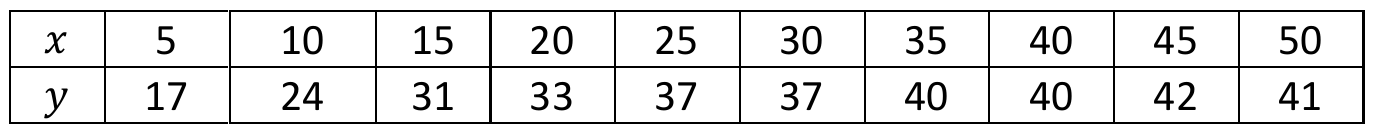

puntosX = [5 10 15 20 25 30 35 40 45 50];
puntosY = [17 24 31 33 37 37 40 40 42 41];


#### i. Ajuste los datos a una línea recta

syms x
grado = 1;

test = regresionPolinomial(puntosX, puntosY, grado);
test = flip(test);

polinomio = vpa(poly2sym(test, x))

$$polinomio = 0.4945\,x+20.6000$$

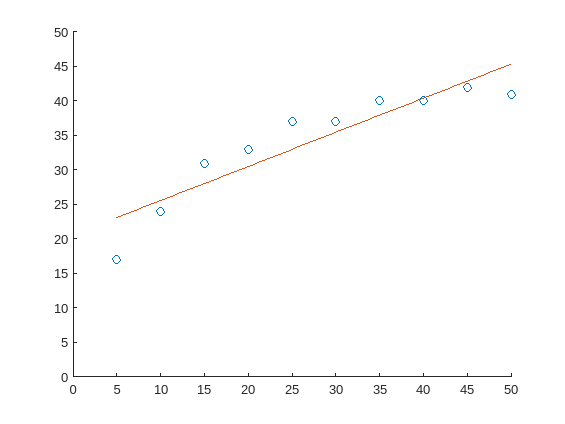

testX = linspace(5, 50, 100);
testY = subs(polinomio, x, testX);

clf
hold on
xlim([0 50])
ylim([0 50])
scatter(puntosX, puntosY)
plot(testX, testY)
hold off

data = table(puntosX', subs(polinomio, x, puntosX)', 'VariableNames', {'puntosX', 'polinomio_values'});
data

data = 8×2 table
    puntosX    polinomio_values
    _______    ________________

       3             64        
       4             125       
       5             216       
       7             512       
       8             729       
       9             1000      
      11             1728      
      12             2197      


Error estándar

error_estandar = sqrt(sum((subs(polinomio, x, puntosX) - puntosY).^2) / (length(puntosY) - 2));
disp(error_estandar)

$$1.2665e+03$$

Coeficiente de correlación

disp(coeficienteCorrelacion(puntosX, puntosY ,subs(polinomio, x, puntosX)))

$$1.1253e+03\,\mathrm{i}$$

Como se observa con el coeficiente de correlacion hay una relación positiva entre las variables y por lo tanto el modelo polinomial se ajusta bien a los datos y puede explicar una gran parte de la variabilidad en *y*.

#### ii. Ajuste los datos a un modelo de tasa de crecimiento de saturación

syms h
crecimientoPolinomio = modeloRazonCrecimiento(puntosX, puntosY)

$$crecimientoPolinomio = \frac{5.4143\,h}{h+5.0186}$$

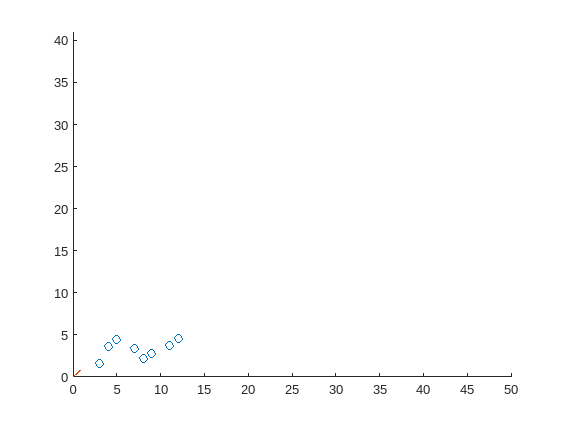

testY = subs(crecimientoPolinomio, h, testX);

clf
hold on
xlim([0 50])
ylim([0 41])
scatter(puntosX, puntosY)
plot(testX, testY)
hold off

data = table(puntosX', vpa(subs(crecimientoPolinomio, h, puntosX))', 'VariableNames', {'puntosX', 'polinomio_values'});
data

data = 8×2 table
    puntosX    polinomio_values
    _______    ________________

       3            2.0257     
       4            2.4014     
       5            2.7022     
       7            3.1535     
       8            3.3271     
       9            3.4760     
      11            3.7180     
      12            3.8177     


Error estándar

error_estandar = sqrt(sum((subs(crecimientoPolinomio, h, puntosX) - puntosY).^2) / (length(puntosY) - 2));
disp(vpa(error_estandar))

$$1.0730$$

Coeficiente de correlación

vpa(coeficienteCorrelacion(puntosX, puntosY,vpa(subs(crecimientoPolinomio, h, puntosX))))

$$ans = 0.3019$$

#### iii. Ajuste los datos a una ecuación de potencias

clf
potencialPolinomio = modeloAjustePotencial(puntosX, puntosY)

$$potencialPolinomio = 1.6111\,h^{0.3500}$$

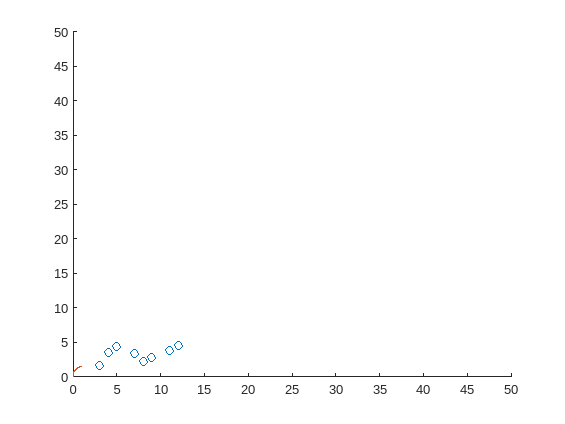

testY = subs(potencialPolinomio, h, testX);

hold on
xlim([0 50])
ylim([0 50])
scatter(puntosX, puntosY)
plot(testX, testY)
hold off

data = table(puntosX', vpa(subs(potencialPolinomio, h, puntosX))', 'VariableNames', {'puntosX', 'polinomio_values'});
data

data = 8×2 table
    puntosX    polinomio_values
    _______    ________________

       3            2.3666     
       4            2.6173     
       5            2.8299     
       7            3.1836     
       8            3.3359     
       9            3.4763     
      11            3.7293     
      12            3.8446     


Error estándar

error_estandar = sqrt(sum((subs(potencialPolinomio, h, puntosX) - puntosY).^2) / (length(puntosY) - 2));
disp(vpa(error_estandar))

$$1.0319$$

Coeficiente de correlación

coeficienteCorrelacion(puntosX, puntosY,vpa(subs(potencialPolinomio, h, puntosX)))

$$ans = 0.3992$$

#### iv. Ajuste los datos a una parábola.

syms x
grado = 2;
test = regresionPolinomial(puntosX, puntosY, grado);
test = flip(test);
polinomio = vpa(poly2sym(test, x))

$$polinomio = 0.0159\,x^{2}-0.1005\,x+3.0323$$

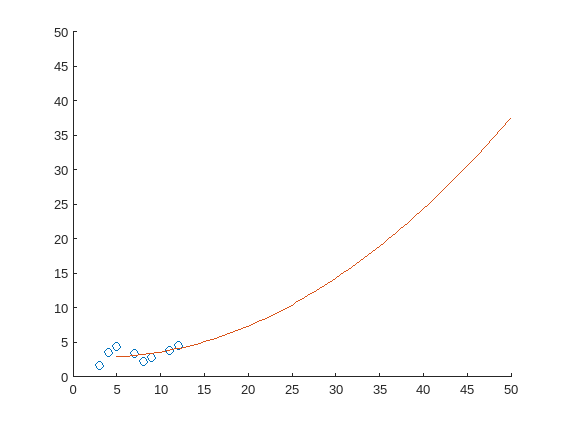

testX = linspace(5, 50, 100);
testY = subs(polinomio, x, testX);
clf
hold on
xlim([0 50])
ylim([0 50])
scatter(puntosX, puntosY)
plot(testX, testY)
hold off

data = table(puntosX', subs(polinomio, x, puntosX)', 'VariableNames', {'puntosX', 'polinomio_values'});
data

data = 8×2 table
    puntosX    polinomio_values
    _______    ________________

       3            2.8735     
       4            2.8840     
       5            2.9262     
       7            3.1058     
       8            3.2431     
       9            3.4122     
      11            3.8455     
      12            4.1097     


Error estándar

error_estandar = sqrt(sum((subs(polinomio, x, puntosX) - puntosY).^2) / (length(puntosY) - 2));
disp(error_estandar)

$$1.0082$$

Coeficiente de correlación

coeficienteCorrelacion(puntosX,puntosY, subs(polinomio, x, puntosX))

$$ans = 0.4445$$

#### v. Grafique la tabla de datos y los ajustes encontrados en el intervalo en que están contenidos los datos.

Este numeral ya se realizo en los anteriores puntos.

#### vi. ¿Existe algún ajuste superior a los demás? Justifique.

Para saber si existe algun ajuste superior, vamos a tener en cuenta el coeficiente de correlación que se calculo de cada método en los anteriores numerales, podemos ver que el coeficiente mas alto fue de 0.9945. Por lo tanto, el ajuste superior a los demás fue el de un ***modelo de regresión de tasa de crecimiento de saturación.***

### b. 

Para la siguiente tabla de datos:

puntosX = [3 4 5 7 8 9 11 12];
puntosY = [1.6 3.6 4.4 3.4 2.2 2.8 3.8 4.6];

#### i. Aproxime los datos mediante un polinomio genérico de grado 3, grado 4 y grado 5.

- ***Grado 3***

syms x
grado = 3;
test = regresionPolinomial (puntosX, puntosY, grado);
test = flip(test);

polinomio = vpa(poly2sym(test, x))

$$polinomio = 0.0467\,x^{3}-1.0412\,x^{2}+7.1438\,x-11.4887$$

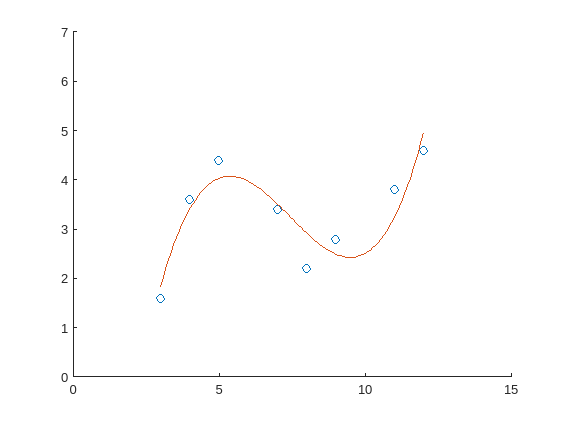

testX = linspace(3, 12, 100);
testY = subs(polinomio, x, testX);

clf
hold on
xlim([0 15])
ylim([0 7])
scatter(puntosX, puntosY)
plot(testX, testY)
hold off

data = table(puntosX', subs(polinomio, x, puntosX)', 'VariableNames', {'puntosX', 'polinomio_values'});
data

data = 8×2 table
    puntosX    polinomio_values
    _______    ________________

       3            1.8321     
       4            3.4145     
       5            4.0347     
       7            3.5087     
       8            2.9227     
       9            2.4947     
      11            3.2330     
      12            4.9595     


Error estándar

error_estandar = sqrt(sum((subs(polinomio, x, puntosX) - puntosY).^2) / (length(puntosY) - 2));
disp(error_estandar)

$$0.4654$$

Coeficiente de correlación

coeficienteCorrelacion(puntosX,puntosY, subs(polinomio, x, puntosX))

$$ans = 0.9105$$

- ***Grado 4***

syms x
grado = 4;
test = regresionPolinomial (puntosX, puntosY, grado);
test = flip(test);

polinomio = vpa(poly2sym(test, x))

$$polinomio = -0.0082\,x^{4}+0.2892\,x^{3}-3.5544\,x^{2}+17.8734\,x-27.2372$$

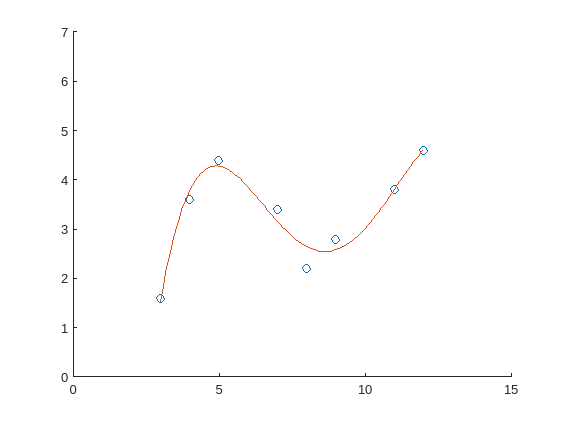

testX = linspace(3, 12, 100);
testY = subs(polinomio, x, testX);

clf
hold on
xlim([0 15])
ylim([0 7])
scatter(puntosX, puntosY)
plot(testX, testY)
hold off

data = table(puntosX', subs(polinomio, x, puntosX)', 'VariableNames', {'puntosX', 'polinomio_values'});
data

data = 8×2 table
    puntosX    polinomio_values
    _______    ________________

       3            1.5352     
       4            3.7885     
       5            4.2782     
       7            3.1575     
       8            2.6492     
       9            2.5813     
      11            3.8001     
      12            4.6101     


Error estándar

error_estandar = sqrt(sum((subs(polinomio, x, puntosX) - puntosY).^2) / (length(puntosY) - 2));
disp(error_estandar)

$$0.2460$$

Coeficiente de correlación

coeficienteCorrelacion(puntosX,puntosY, subs(polinomio, x, puntosX))

$$ans = 0.9758$$

- ***Grado 5***

syms x
grado = 5;
test = regresionPolinomial (puntosX, puntosY, grado);
test = flip(test);

polinomio = vpa(poly2sym(test, x))

$$polinomio = -8.2971e-04\,x^{5}+0.0230\,x^{4}-0.1591\,x^{3}-0.5182\,x^{2}+8.2494\,x-15.8784$$

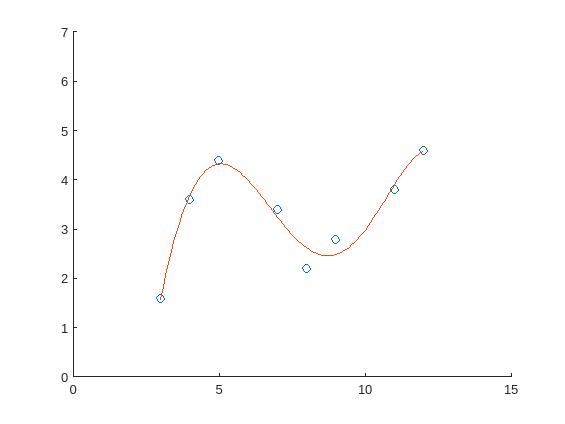

testX = linspace(3, 12, 100);
testY = subs(polinomio, x, testX);

clf
hold on
xlim([0 15])
ylim([0 7])
scatter(puntosX, puntosY)
plot(testX, testY)
hold off

data = table(puntosX', subs(polinomio, x, puntosX)', 'VariableNames', {'puntosX', 'polinomio_values'});
data

data = 8×2 table
    puntosX    polinomio_values
    _______    ________________

       3            1.5737     
       4            3.6905     
       5            4.3242     
       7            3.2440     
       8            2.6180     
       9            2.4860     
      11            3.8936     
      12            4.5700     


Error estándar

error_estandar = sqrt(sum((subs(polinomio, x, puntosX) - puntosY).^2) / (length(puntosY) - 2));
disp(error_estandar)

$$0.2317$$

Coeficiente de correlación

coeficienteCorrelacion(puntosX,puntosY, subs(polinomio, x, puntosX))

$$ans = 0.9786$$

#### ii. Aproxime los datos mediante funciones ortogonales (Polinomios de Legendre).

% Note que esta en el intervalo [3, 12] y tiene que estar en [-1, 1]
syms x
grado = 2;
polinomio = vpa(interpolacionLagrangeSinFuncion(puntosX, puntosY))

$$polinomio = 9.0774e-04\,x^{7}-0.0460\,x^{6}+0.9635\,x^{5}-10.8097\,x^{4}+70.0403\,x^{3}-262.4443\,x^{2}+528.6952\,x-440.6000$$


funcionParaDevolvermeIntervaloOriginal = 2/9*x-5/3;
funcionIntervaloCorrecto = (x+(5/3))*(9/2);

polinomio = subs(polinomio,x,funcionIntervaloCorrecto);
polinomio = polinomiosDeLegendre(polinomio, "legendre", 3);
polinomio = subs(polinomio,x,funcionParaDevolvermeIntervaloOriginal)

$$polinomio = 1.8140\,\left(0.2222\,x-1.6667\right)\,\left(1.5000\,{\left(0.2222\,x-1.6667\right)}^{2}-0.5000\right)-0.1705\,x+0.1301\,{\left(0.2222\,x-1.6667\right)}^{2}+4.8003$$

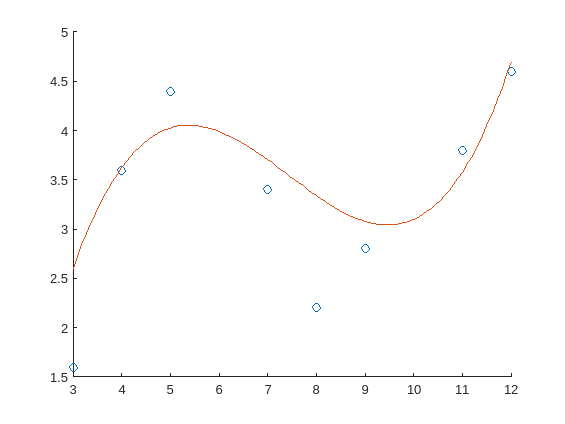

testX = linspace(3, 12, 100);
testY = subs(polinomio, x, testX);

clf
hold on
scatter(puntosX, puntosY)
plot(testX, testY)
hold off

data = table(puntosX', subs(polinomio, x, puntosX)', 'VariableNames', {'puntosX', 'polinomio_values'});
data

data = 8×2 table
    puntosX    polinomio_values
    _______    ________________

       3            2.6050     
       4            3.6223     
       5            4.0254     
       7            3.7056     
       8            3.3410     
       9            3.0789     
      11            3.5785     
      12            4.6987     


Error estándar

error_estandar = sqrt(sum((subs(polinomio, x, puntosX) - puntosY).^2) / (length(puntosY) - 2));
disp(error_estandar)

$$0.6687$$

Coeficiente correlación

coeficienteCorrelacion(puntosX, puntosY,subs(polinomio, x, puntosX))

$$ans = 0.8044$$

#### iii. Grafique la tabla de datos y los polinomios de aproximación obtenidos en el intervalo en que están contenidos los datos.

#### iv. Encuentre el error estimado y el coeficiente de correlación.

Estos numerales ya se resolvieron en los puntos anteriores.

### c. Utilizando polinomios de Legendre:

#### i. Sea la función $f(x) = e^x$ en el intervalo [−1, 1]. Aproxime la función mediante una recta y una parábola de mínimos cuadrados. Compare las dos gráficas.

syms x
f = exp(x);
test = polinomiosDeLegendre(f, "legendre", 1);
disp(test)

$$1.1036\,x+1.1752$$

test2 = polinomiosDeLegendre(f, "legendre", 2);
disp(test2)

$$0.5368\,x^{2}+1.1036\,x+0.9963$$

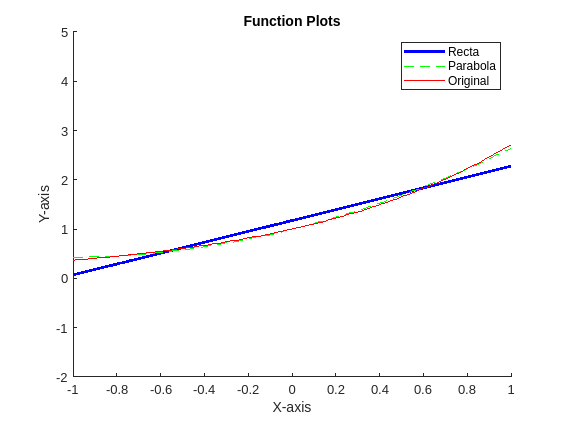

testX = linspace(-1, 1, 100);
testY = subs(test, x, testX);
testY2 = subs(test2, x, testX);
originalY = vpa(subs(f, x, testX));

clf
hold on
plot(testX, testY, 'LineWidth', 2, 'DisplayName', 'Recta', 'Color', 'blue')
plot(testX, testY2, 'LineStyle', '--', 'DisplayName', 'Parabola', 'Color', 'green')
plot(testX, originalY, 'DisplayName', 'Original', 'Color', 'red')

xlim([-1 1]);
ylim([-2 5]);

legend('show');

xlabel('X-axis');
ylabel('Y-axis');
title('Function Plots');
hold off

#### ii. Aproxime la función $f(x) = \frac{1}{x}
$ en el intervalo [1, 2] por una recta, una parábola y una ecuación cúbica de mínimos cuadrados. Compare gráficamente.

f = 1/x;
b = 2;
a = 1;

fIntervaloCorrecto = ((b-a)*(x+1))/2 + a;   %x
fParaDevolverme = 2*(x-a)/(b-a)-1;          %t
polinomio = subs(f,x,fIntervaloCorrecto)

$$polinomio = \frac{1}{0.5000\,x+1.5000}$$

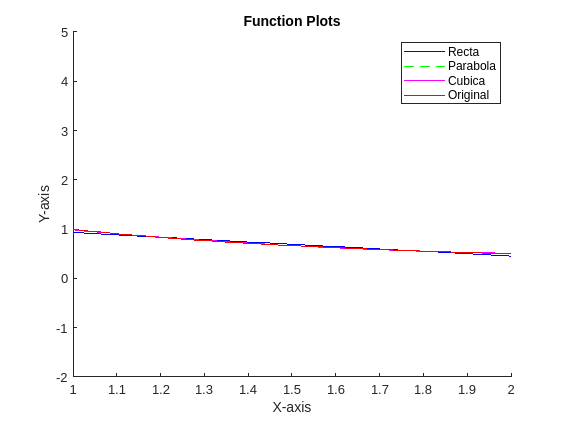

test = polinomiosDeLegendre(polinomio, "legendre", 1);
test2 = polinomiosDeLegendre(polinomio, "legendre", 2);
test3 = polinomiosDeLegendre(polinomio, "legendre", 3);

test = subs(test,x, fParaDevolverme);
test2 = subs(test2,x, fParaDevolverme);
test3 = subs(test3,x, fParaDevolverme);

testX = linspace(1, 2, 100);
testY = subs(test, x, testX);
testY2 = subs(test2, x, testX);
testY3 = subs(test3, x, testX);
originalY = vpa(subs(f, x, testX));

clf
hold on
plot(testX, testY, 'DisplayName', 'Recta', 'Color', 'blue')
plot(testX, testY2, 'LineStyle', '--', 'DisplayName', 'Parabola', 'Color', 'green')
plot(testX, testY2, 'LineStyle', '-', 'DisplayName', 'Cubica', 'Color', 'magenta')
plot(testX, originalY, 'DisplayName', 'Original', 'Color', 'red')

xlim([1 2]);
ylim([-2 5]);

legend('show');

xlabel('X-axis');
ylabel('Y-axis');
title('Function Plots');
hold off

#### iii. Aproxime la función $f(x) = (2x)^3$ en el intervalo [0, 1] mediante una recta y una parábola de mínimos cuadrados. Compare las dos gráficas.

syms x
f = (2*x)^3

$$f = 8\,x^{3}$$

b = 1;
a = 0;

fIntervaloCorrecto = ((b-a)*(x+1))/2 + a;   %x
fParaDevolverme = 2*(x-a)/(b-a)-1;          %t
polinomio = subs(f,x,fIntervaloCorrecto)

$$polinomio = 8\,{\left(0.5000\,x+0.5000\right)}^{3}$$

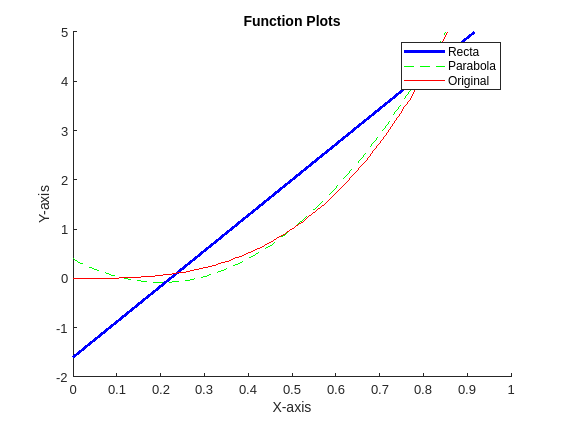

test = polinomiosDeLegendre(polinomio, "legendre", 1);
test2 = polinomiosDeLegendre(polinomio, "legendre",2);

test = subs(test,x, fParaDevolverme);
test2 = subs(test2,x, fParaDevolverme);

testX = linspace(0, 1, 100);
testY = subs(test, x, testX);
testY2 = subs(test2, x, testX);
originalY = vpa(subs(f, x, testX));

clf
hold on
plot(testX, testY, 'LineWidth', 2, 'DisplayName', 'Recta', 'Color', 'blue')
plot(testX, testY2, 'LineStyle', '--', 'DisplayName', 'Parabola', 'Color', 'green')
plot(testX, originalY, 'DisplayName', 'Original', 'Color', 'red')

xlim([0 1]);
ylim([-2 5]);

legend('show');

xlabel('X-axis');
ylabel('Y-axis');
title('Function Plots');
hold off

### d. Utilice las series de Fourier para encontrar la aproximación de:

#### i. La siguiente función:

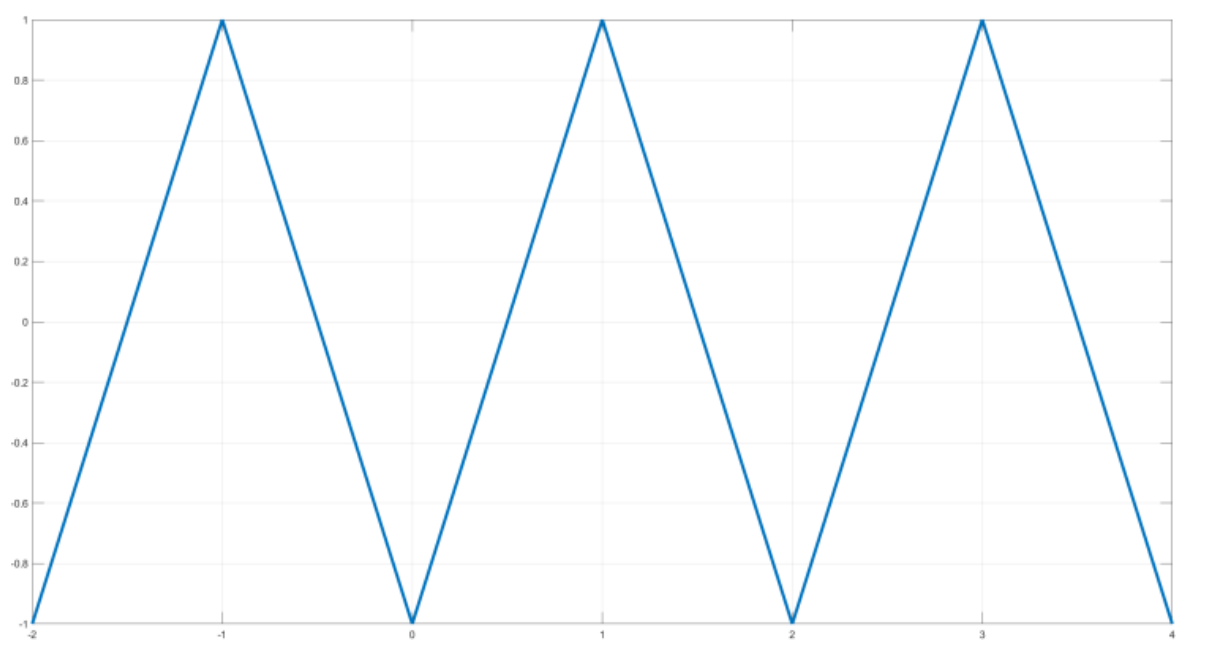

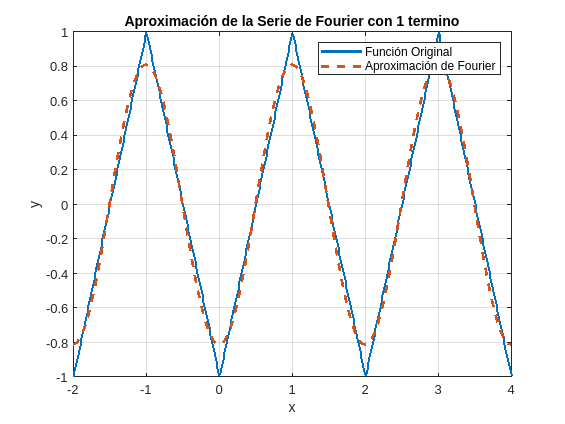

f = @(x) (2*x + 3).*(x >= -2 & x <= -1) + (-2*x - 1).*(x > -1 & x <= 0) + (2*x - 1).*(x > 0 & x <= 1) + (-2*x + 3).*(x > 1 & x <= 2) ...
+ (2*x - 5).*(x > 2 & x <= 3) + (-2*x + 7).*(x > 3 & x <= 4);

T = 2;  
N = 1;  

fourier_series = stf(f, T, N, -1, -1);
x_vals = linspace(-2, 4, 500);  
y_vals = f(x_vals);
y_fourier = fourier_series(x_vals);

figure;
plot(x_vals, y_vals, 'LineWidth', 2, 'DisplayName', 'Función Original');

hold on;
plot(x_vals, y_fourier, '--', 'LineWidth', 2, 'DisplayName', 'Aproximación de Fourier');
xlabel('x');
ylabel('y');
title('Aproximación de la Serie de Fourier con 1 termino');
legend('show');
grid on;
hold off;

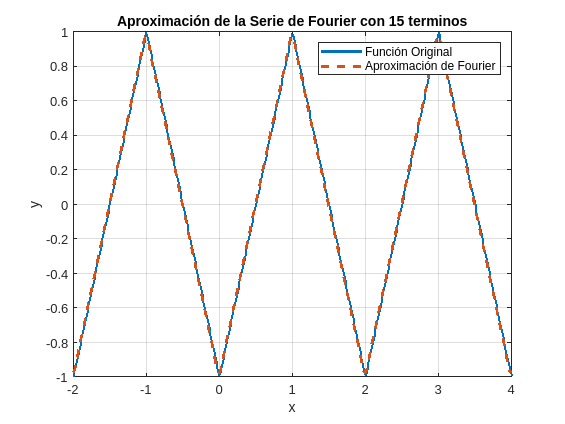

N2 = 15;  

fourier_series = stf(f, T, N2, -1, -1);
x_vals = linspace(-2, 4, 500);  
y_vals = f(x_vals);
y_fourier = fourier_series(x_vals);

figure;
plot(x_vals, y_vals, 'LineWidth', 2, 'DisplayName', 'Función Original');

hold on;
plot(x_vals, y_fourier, '--', 'LineWidth', 2, 'DisplayName', 'Aproximación de Fourier');
xlabel('x');
ylabel('y');
title('Aproximación de la Serie de Fourier con 15 terminos');
legend('show');
grid on;
hold off;

#### ii. La siguiente tabla de datos:

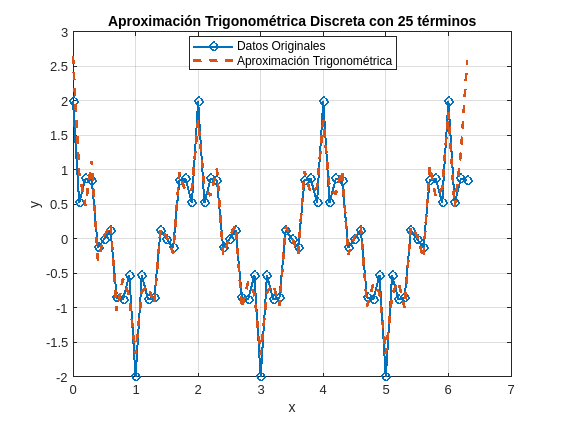

x_data = [0, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1.0, 1.1, 1.2, 1.3, 1.4, 1.5, 1.6, 1.7, 1.8, 1.9, 2.0, 2.1, 2.2, 2.3, 2.4, 2.5, 2.6, 2.7, 2.8, 2.9, 3.0, 3.1, 3.2, 3.3, 3.4, 3.5, 3.6, 3.7, 3.8, 3.9, 4.0, 4.1, 4.2, 4.3, 4.4, 4.5, 4.6, 4.7, 4.8, 4.9, 5.0, 5.1, 5.2, 5.3, 5.4, 5.5, 5.6, 5.7, 5.8, 5.9, 6.0, 6.1, 6.2, 6.3];
y_data = [1.9990, 0.5253, 0.8726, 0.8509, -0.1269, 0.0000, 0.1269, -0.8509, -0.8726, -0.5253, -1.9990, -0.5253, -0.8726, -0.8509, 0.1269, 0.0000, -0.1269, 0.8509, 0.8726, 0.5253, 1.9990, 0.5253, 0.8726, 0.8509, -0.1269, 0.0000, 0.1269, -0.8509, -0.8726, -0.5253, -1.9990, -0.5253, -0.8726, -0.8509, 0.1269, 0.0000, -0.1269, 0.8509, 0.8726, 0.5253, 1.9990, 0.5253, 0.8726, 0.8509, -0.1269, 0.0000, 0.1269, -0.8509, -0.8726, -0.5253, -1.9990, -0.5253, -0.8726, -0.8509, 0.1269, 0.0000, -0.1269, 0.8509, 0.8726, 0.5253, 1.9990, 0.5253, 0.8726, 0.8509];

m = length(x_data)/2;
n = 25; 

Sn = trigonometric_approx(x_data, y_data, m, n);